# Leo Berman & Justin Ok Project 4 Code

## Step 0

clear;
data = load("ecg_data.txt");
t = data(:,1);
x = data(:,2);
fs = 1000;

## Step 1

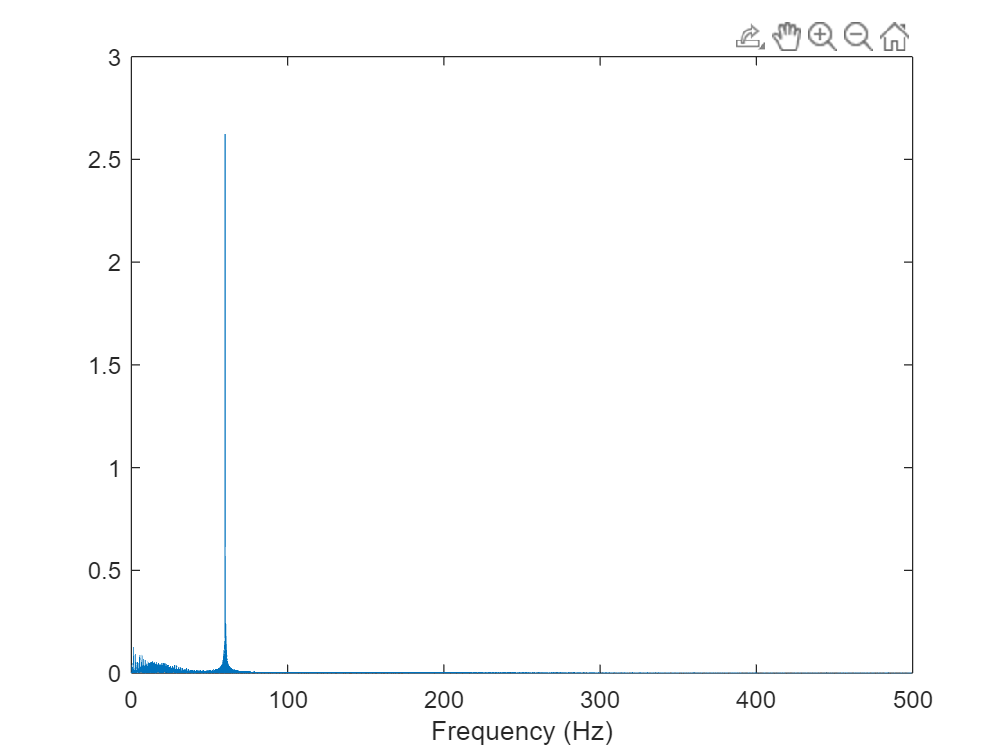

myFFT(x,fs);

## Step 2

### RC Low Pass Filter

R = 1000000;
C = .000001;
syms s
Zr = R;
Zc = 1/(s*C);
Vout = simplify((Zc/(Zr+Zc)))

$$Vout = \frac{1}{s+1}$$

Hf = tf(1,[1 1])

Hf =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



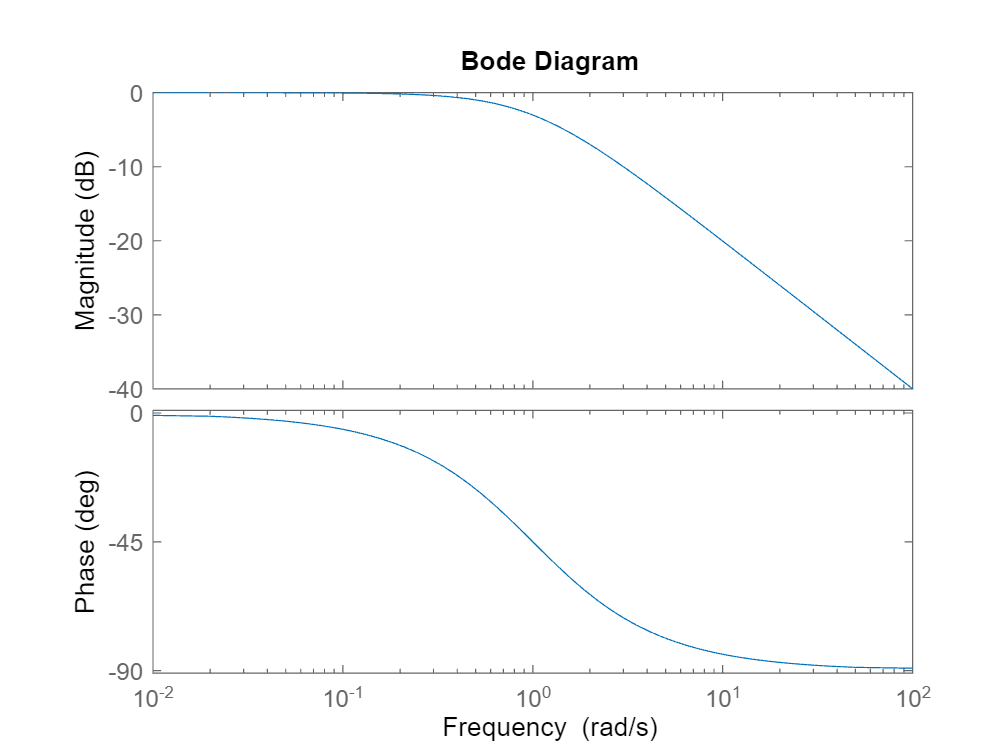

bodeplot(Hf)

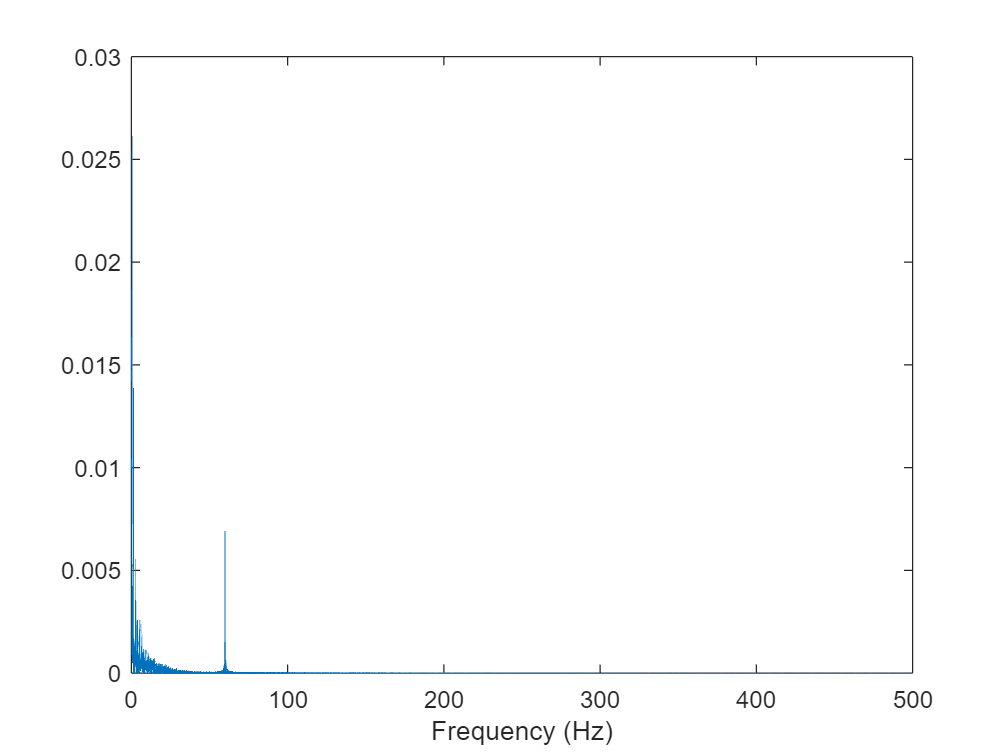

RCFilteredSignal = lsim(Hf,x,t);
myFFT(RCFilteredSignal,fs)

### RLC Band Stop Filter

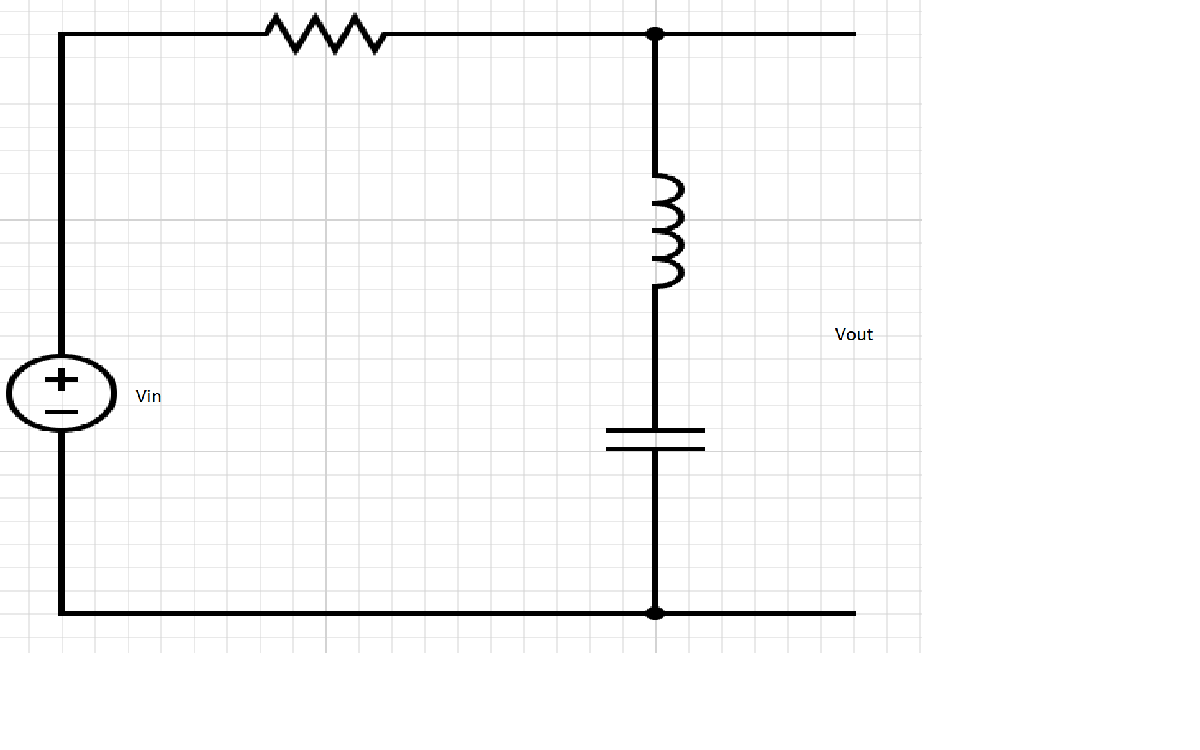

R = 128000;
L = 20;
C = .000014;
syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vout = simplify(((Zl+Zc))/(Zr+Zl+Zc))

$$Vout = \frac{41320706725109395\,s^{2}+147573952589676412928}{41320706725109395\,s^{2}+264452523040700128000\,s+147573952589676412928}$$

Hf = tf([L/((1/C)) 0 1],[L/((1/C)) (R*10)/((1/C)) 1])

Hf =
 
       0.00028 s^2 + 1
  -------------------------
  0.00028 s^2 + 17.92 s + 1
 
Continuous-time transfer function.



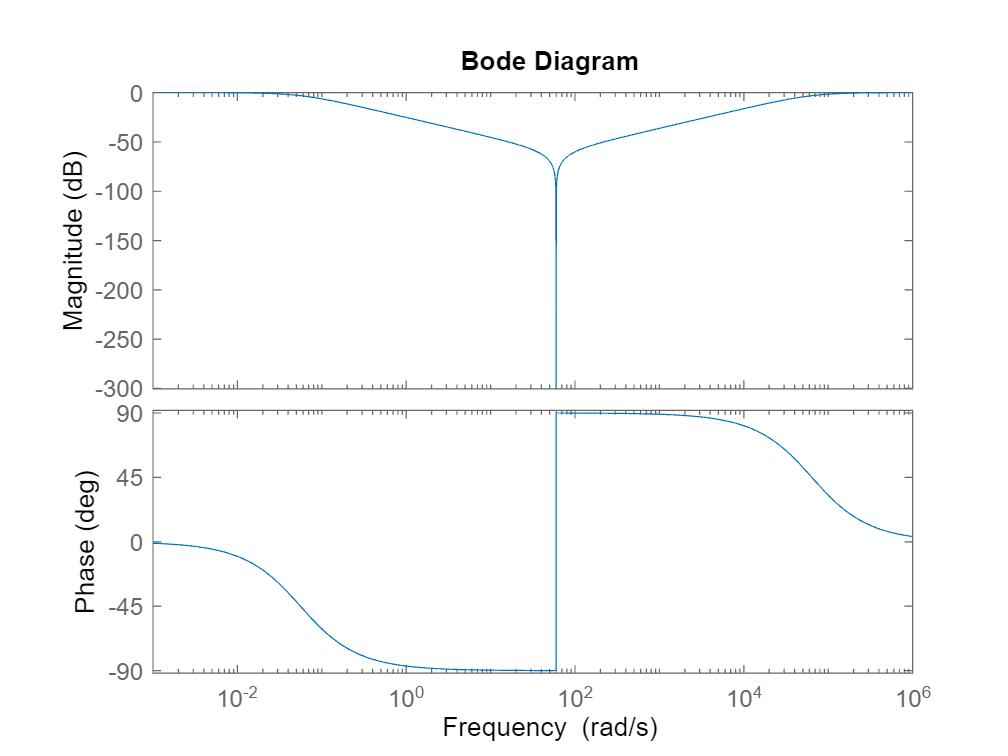

bodeplot(Hf)

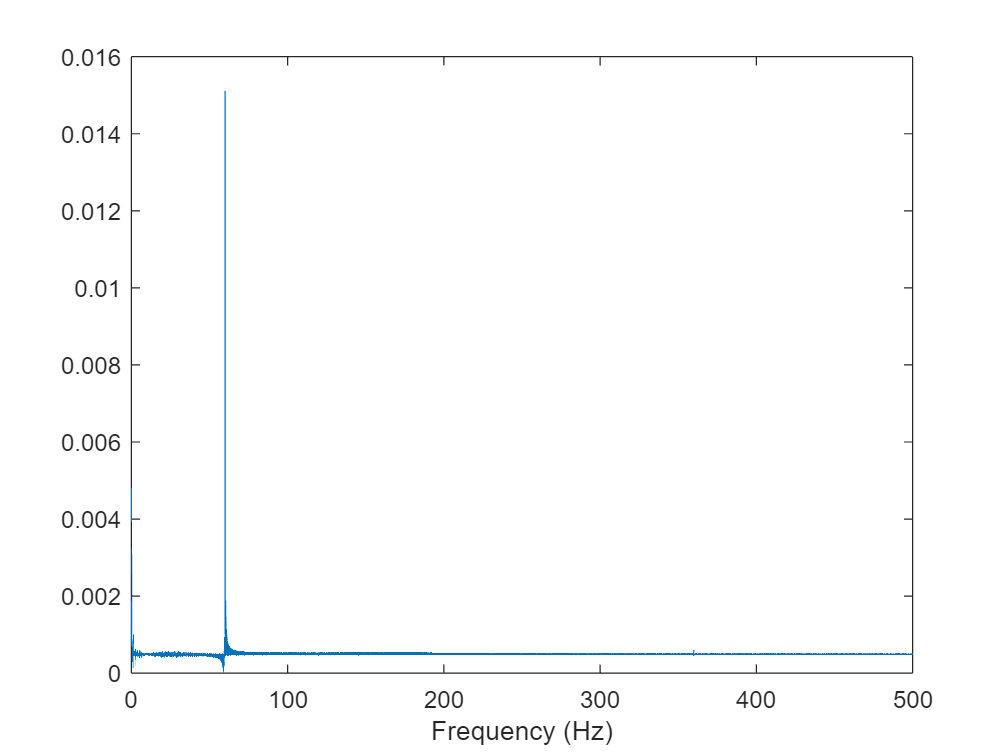

RLCStopFilteredSignal = lsim(Hf,x,t);
myFFT(RLCStopFilteredSignal,fs)

### RLC Lowpass Filter

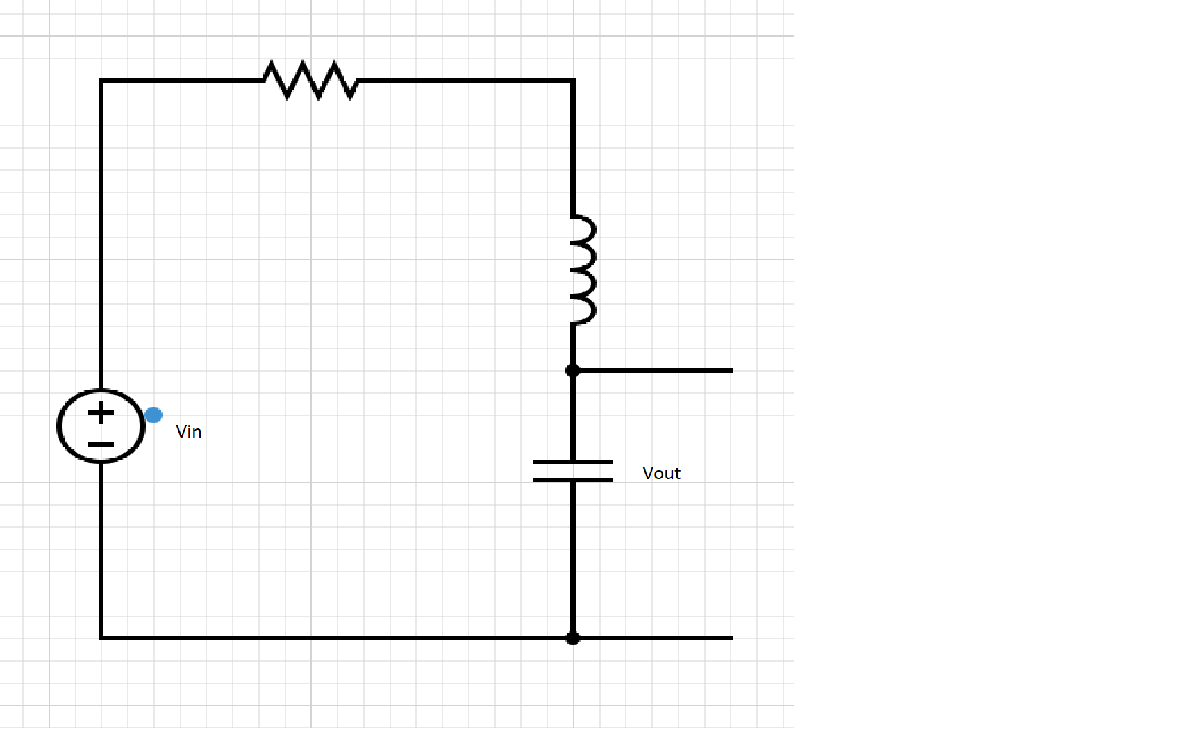

R = 1000;
L = .3;
C = .0001;
syms s
Zr = R;
Zl = s*L;
Zc = 1/(C*s);
Vout =simplify(Zc/(Zl+Zr+Zc))

$$Vout = \frac{100000}{3\,s^{2}+10000\,s+100000}$$

Hf = tf(1, [L/((1/C)) (R)/((1/C)) 1])

Hf =
 
            1
  ---------------------
  3e-05 s^2 + 0.1 s + 1
 
Continuous-time transfer function.



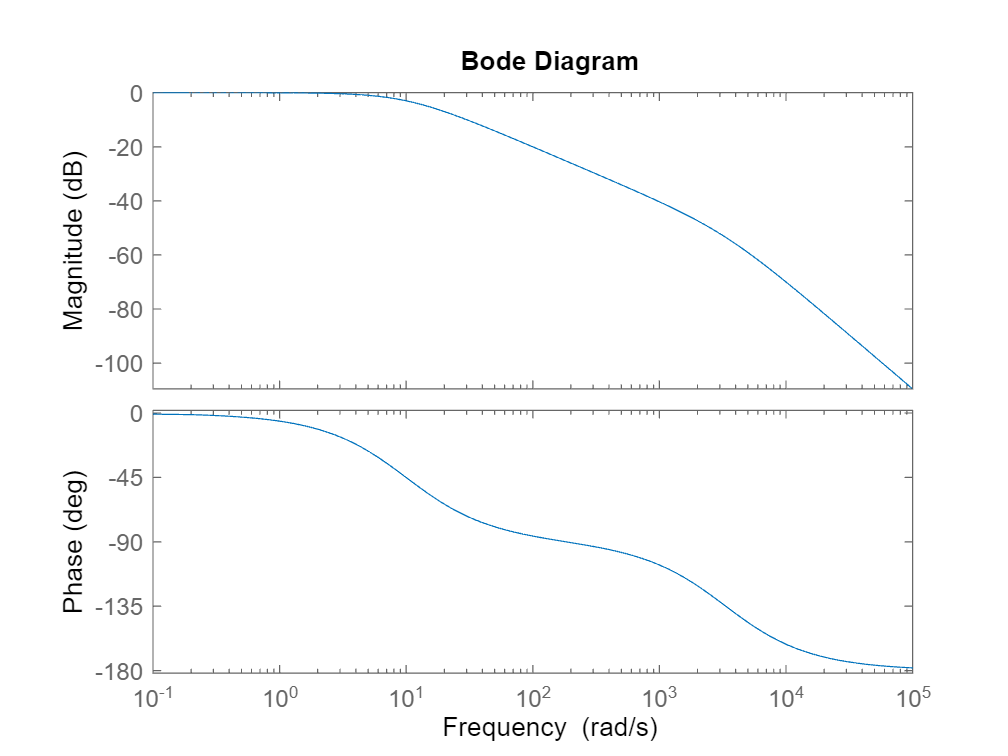

bodeplot(Hf)

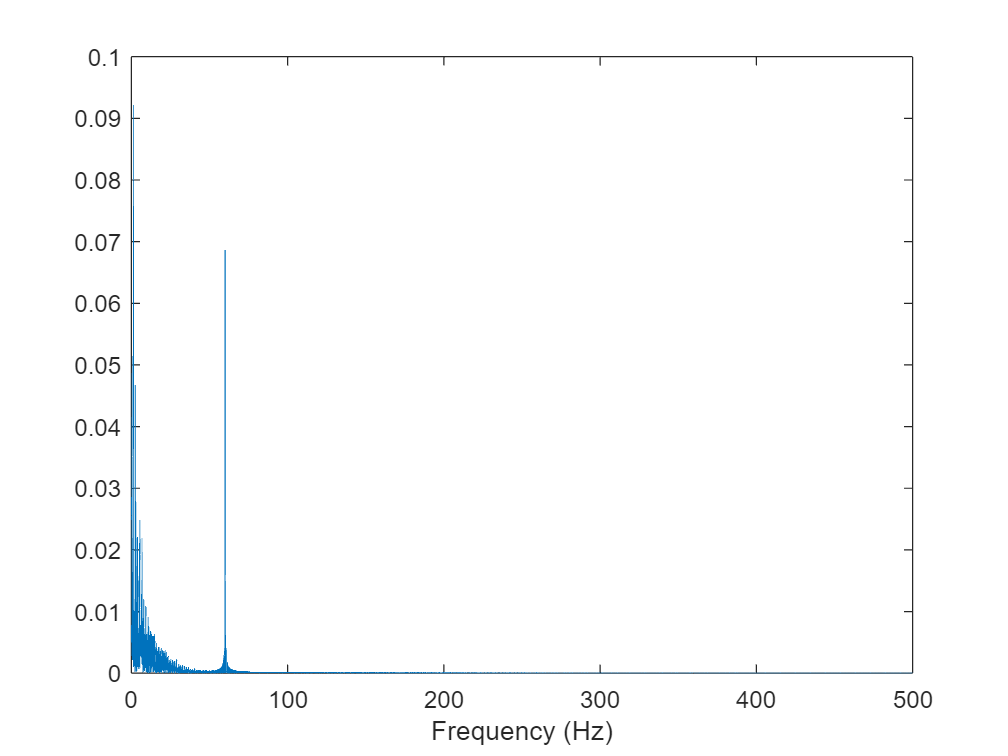

RLCLowpassFilteredSignal = lsim(Hf,x,t);
myFFT(RLCLowpassFilteredSignal,fs)

### Butter Filter

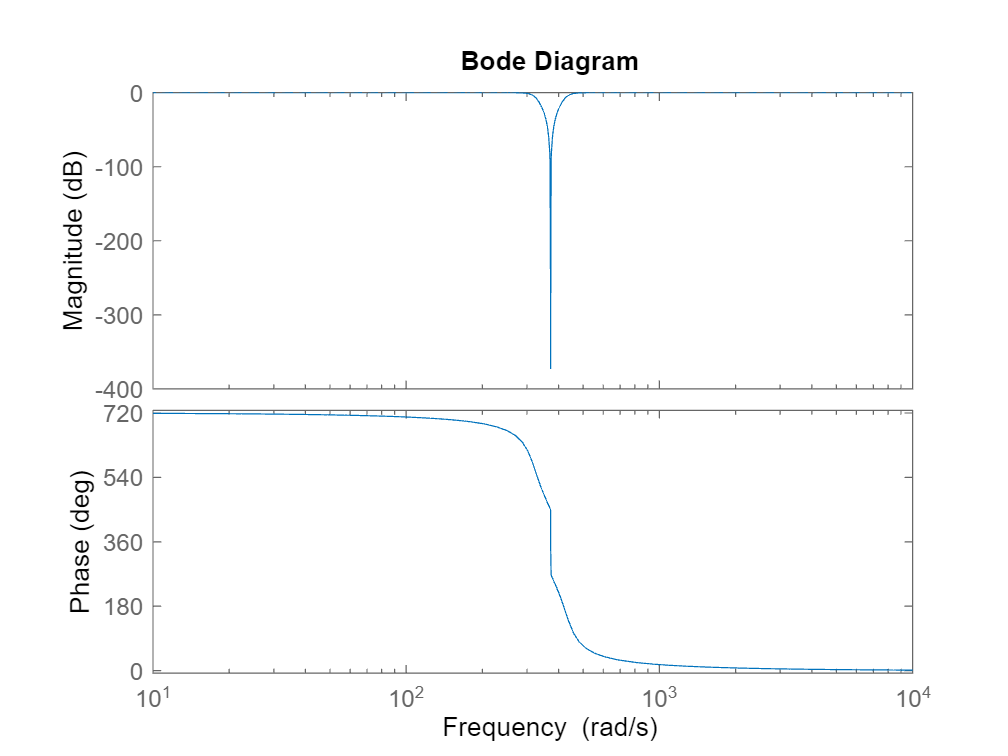

[num,den] = butter(3,[2*pi*50 2*pi*70],'stop','s');
Hf = tf(num,den);
bodeplot(Hf)

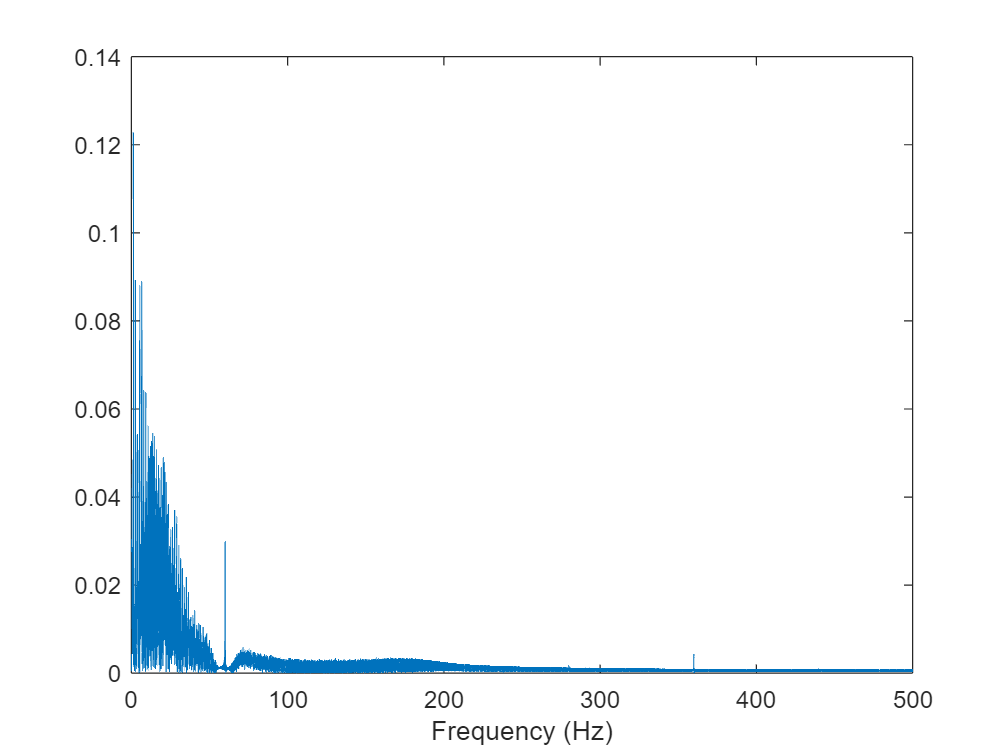

ButterFilteredSignal = lsim(Hf,x,t);
myFFT(ButterFilteredSignal,fs)

[https://www.electronics-tutorials.ws/filter/filter_2.html](https://www.electronics-tutorials.ws/filter/filter_2.html) 

[https://nicadd.niu.edu/~fortner/course/phys475/lect/p575_07a.pdf](https://nicadd.niu.edu/~fortner/course/phys475/lect/p575_07a.pdf) 

[https://coertvonk.com/physics/rlc-filters/rlc-low-pass-filter/two-pole-low-pass-rlc-filter-13594](https://coertvonk.com/physics/rlc-filters/rlc-low-pass-filter/two-pole-low-pass-rlc-filter-13594) 